# Generating noise

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

Acknoledgement: the author would like to thank W. Owen Brimijoin for his Matlab code for generating the colored noise.

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter4/Noise Generation'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

This notebook relies on the finction additive_noise_model.m that allows us to simulate different types of noise. The noise will be added to 1 Hz sinewave simulating the heartbeat. We will simulate: 

- 60 Hz noise

- motion artifacts that are continous

- impulse noise

- brown + impulse + medium frequency noise

fs=250;
N=10000;
T=1/fs;
t = (0:N-1)*T;  
beat_freq=1; 
s=sin(2*pi*t*beat_freq);
plot(t,s);
    title('Signal of interest')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')

## White and 60 Hz noise 

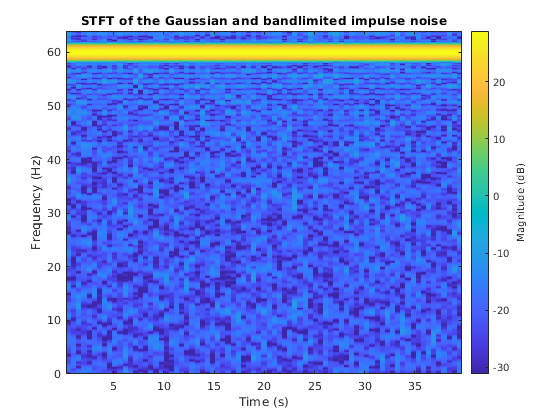

s1=s+additive_noise_model(N, fs, 'Gaussian', [0, 0.01], '60 Hz', [0.4], 'Plotting');

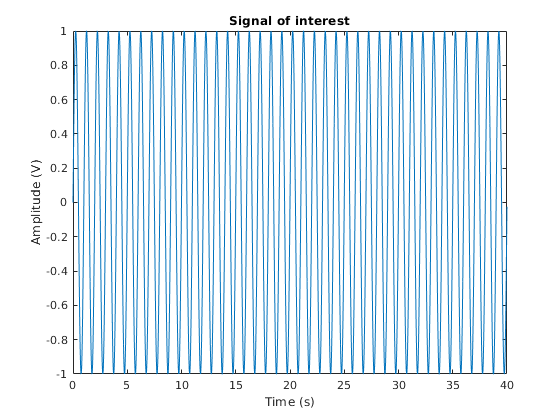

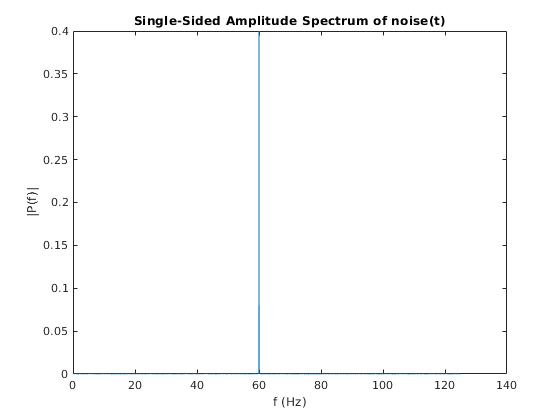

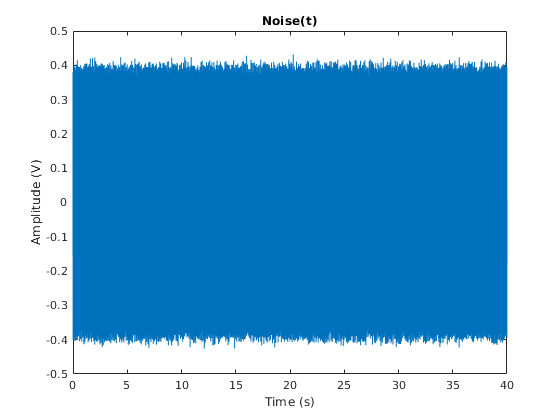

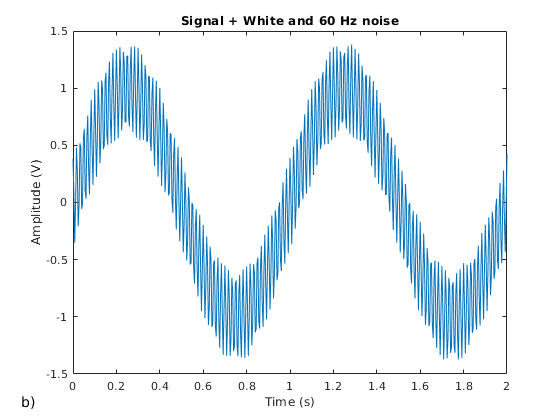

plot(t,s1)
title('Signal + White and 60 Hz noise')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    xlim([0,2])
    annonation_save('b)',"Fig4.6b.jpg", SAVE_FLAG);

## Continous motion artifacts 

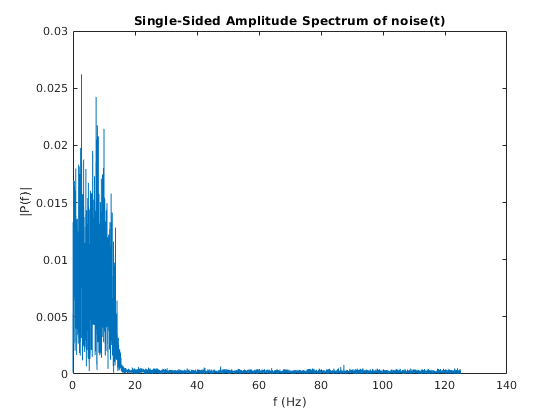

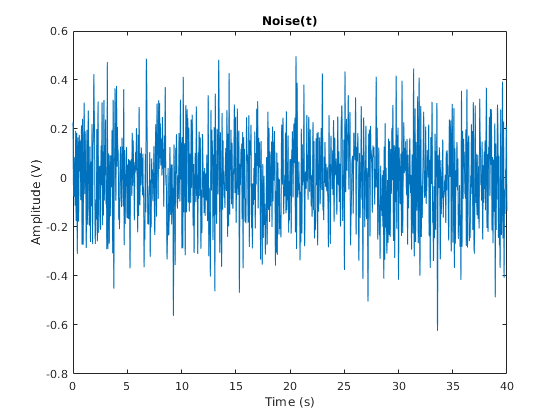

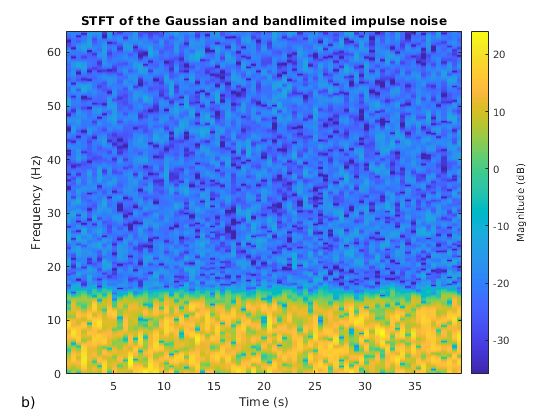

s1=s+additive_noise_model(N, fs, 'Gaussian', [0, 0.01], 'Lowpass', [0.5, 10], 'Plotting');
annonation_save('b)',"Fig4.7b.jpg", SAVE_FLAG);

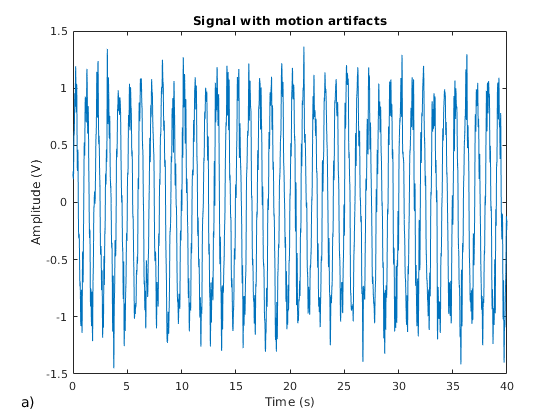

plot(t,s1)
title('Signal with motion artifacts')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    annonation_save('a)',"Fig4.7a.jpg", SAVE_FLAG);

## Baseline shift

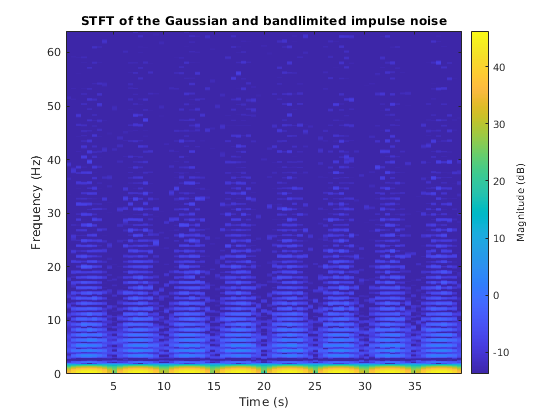

noise=0.5+additive_noise_model(N, fs, 'Gaussian', [0, 0.01], 'NarrowBand', [1.5, 0.1], 'Plotting');

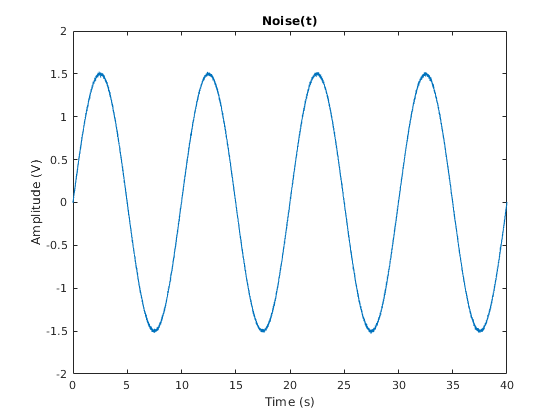

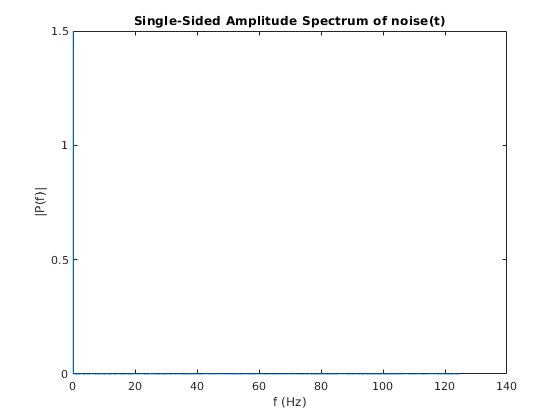

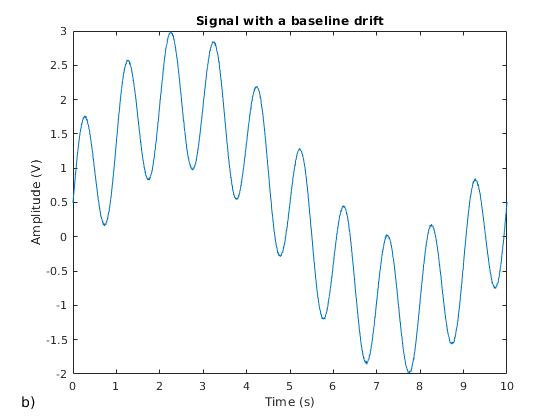

s1=s+noise;
plot(t,s1)
title('Signal with a baseline drift')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    xlim([0,10])
    annonation_save('b)',"Fig4.6b.jpg", SAVE_FLAG);

## Impulse noise

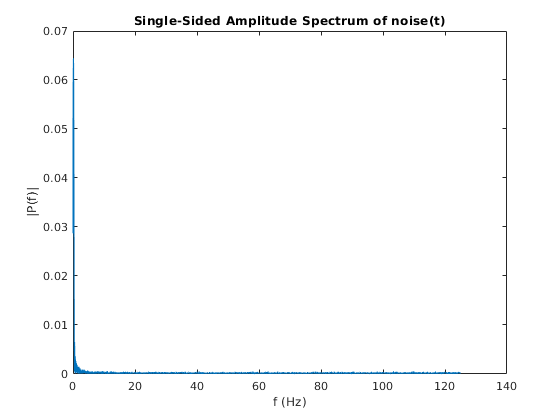

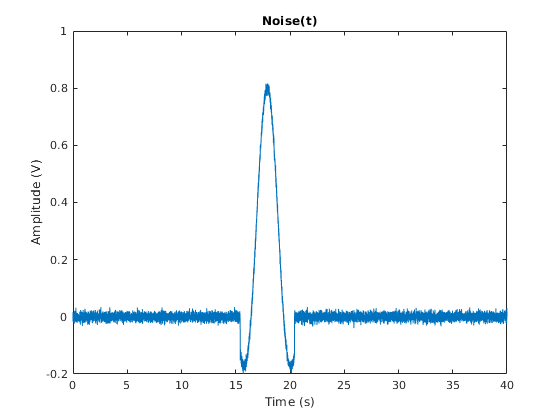

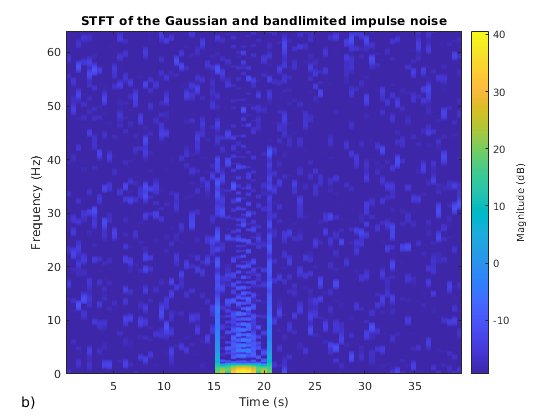

noise=additive_noise_model(N, fs, 'Gaussian', [0, 0.01], 'Impulse', [1.2, 1.5], 'Plotting');
annonation_save('b)',"Fig4.8b.jpg", SAVE_FLAG);

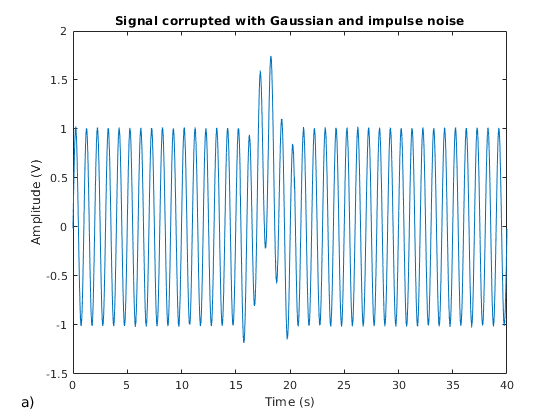

s1=s+noise;
plot(t,s1)
%title('Signal + impulse noise')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    
title('Signal corrupted with Gaussian and impulse noise')
annonation_save('a)',"Fig4.8a.jpg", SAVE_FLAG);

## Brown + impulse + medium frequency noise

This is the noise signal generated based on the model proposed in [Li09] in which the brown noise if generated first and then filtered in the range between 1.5 and 18 Hz. This noise corresponds to motian artifact such as moving clothes over the transducer.

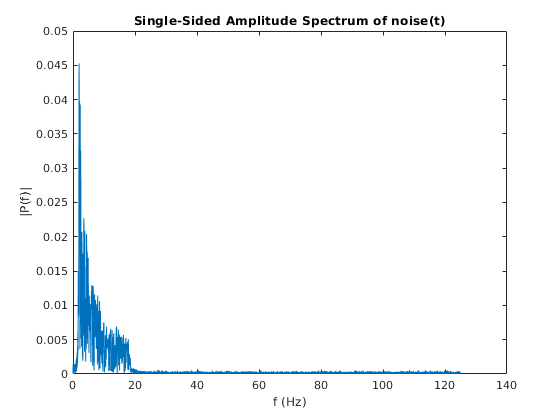

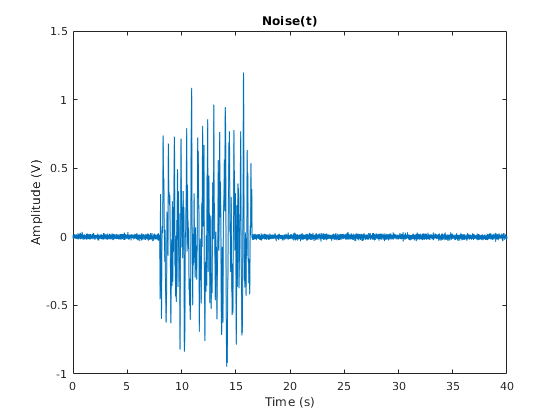

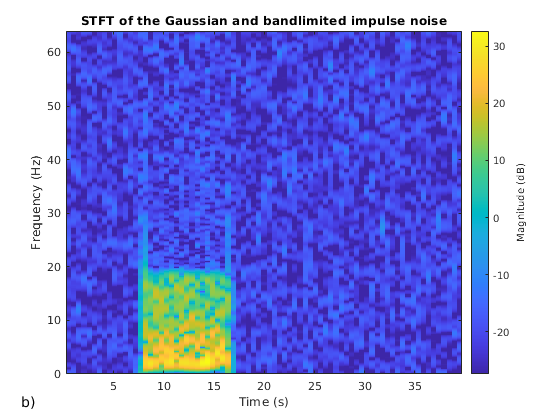

s1=s+additive_noise_model(N, fs, 'BandLimited Impulse', [5, 1.8, 18], 'Gaussian', [0, 0.01],'Plotting');
annonation_save('b)',"Fig4.9b.jpg", SAVE_FLAG);

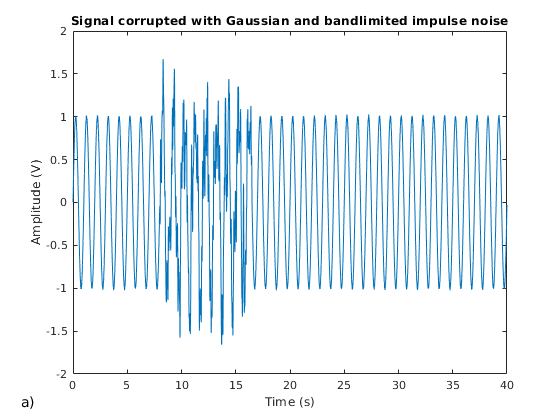

plot(t,s1)
%title('Signal + Brown + impulse + bandpass noise')
    xlabel('Time (s)')
    ylabel('Amplitude (V)')
    
title('Signal corrupted with Gaussian and bandlimited impulse noise')
annonation_save('a)',"Fig4.9a.jpg", SAVE_FLAG);

## References

[Li09] Q. Li et al, "Artificial arterial blood pressure artifact model and an evaluation of a robust blood pressure and heart rate estimator," BioMedical Engineering OnLine volume 8, Article number: 13 (2009).